# cross coupling

%init
clear all
cd("C:\Users\User\OneDrive\DTU\DTU 4-2-2020\DTU\6. semester\bachelor projekt\Previous work\Bachelor-main\Bachelor-main\Simulation_Bachelor_Project\Matlab")
load("crossCoupling.mat")
time,in2,out2,p12z12,

time =          0
    0.0010
    0.0020
    0.0030
    0.0040
    0.0050
    0.0060
    0.0070
    0.0080
    0.0090


in2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


out2 =     0.0038
    0.0039
    0.0039
    0.0040
    0.0040
    0.0041
    0.0041
    0.0042
    0.0042
    0.0043


p12z12 =
 
  From input "u1" to output "y1":
                                                                                                                                 
  -0.01708 s^12 - 211.9 s^11 + 1.047e05 s^10 + 2.913e06 s^9 + 2.871e08 s^8 + 3.914e09 s^7 + 7.193e10 s^6 + 5.379e11 s^5          
                                                                                                                                 
                                                             + 4.456e12 s^4 + 1.385e13 s^3 + 3.784e13 s^2 + 4.012e13 s - 3.108e11
                                                                                                                                 
  -------------------------------------------------------------------------------------------------------------------------------
                                                                                                                                 
  s^12 + 518.6 s^11 + 3.666e04 s^10 + 2.408e0

H_yaw_mixer_to_vel

H_yaw_mixer_to_vel =
 
  From input "Yaw mixer" to output "Yaw velocity":
                                                                                                                                  
   561.7 s^31 + 1.035e06 s^30 + 5.541e08 s^29 + 1.297e11 s^28 + 1.917e13 s^27 + 1.966e15 s^26 + 1.505e17 s^25 + 9.05e18 s^24      
                                                                                                                                  
           + 4.277e20 s^23 + 1.544e22 s^22 + 4.178e23 s^21 + 8.566e24 s^20 + 1.365e26 s^19 + 1.709e27 s^18 + 1.634e28 s^17        
                                                                                                                                  
           + 1.112e29 s^16 + 4.699e29 s^15 + 7.455e29 s^14 - 3.152e30 s^13 - 1.975e31 s^12 - 3.917e31 s^11 - 1.18e31 s^10         
                                                                                                                                  
         

tol=1.5e-1

tol = 0.1500

clf
step(H_yaw_mixer_to_vel)
hold on
step(minreal(H_yaw_mixer_to_vel,tol))
hold off
H_yaw_mixer_to_vel_trimmed=minreal(H_yaw_mixer_to_vel,tol)

H_yaw_mixer_to_vel_trimmed =
 
  From input "Yaw mixer" to output "Yaw velocity":
                                                                                                                                 
  561.7 s^13 + 2.843e05 s^12 + 2.817e07 s^11 + 1.988e09 s^10 + 1.124e11 s^9 + 4.024e12 s^8 + 7.354e13 s^7 + 9.462e14 s^6         
                                                                                                                                 
                                              + 1.032e16 s^5 + 3.936e16 s^4 - 1.526e17 s^3 - 7.252e17 s^2 + 1.159e18 s + 9.974e16
                                                                                                                                 
  -------------------------------------------------------------------------------------------------------------------------------
                                                                                                                                 
  s^15 +

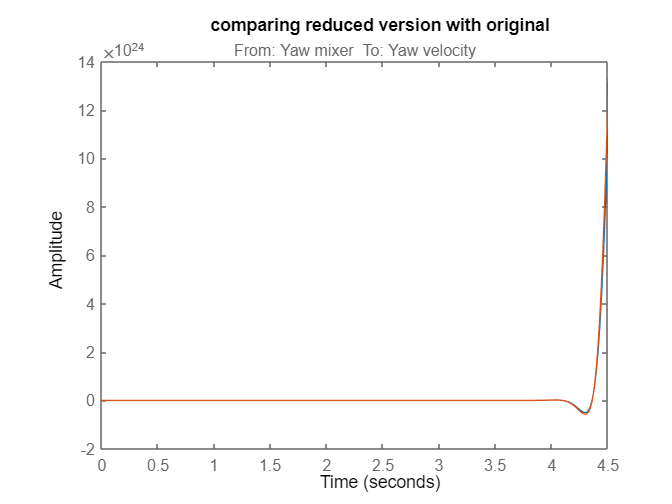

title("comparing reduced version with original")

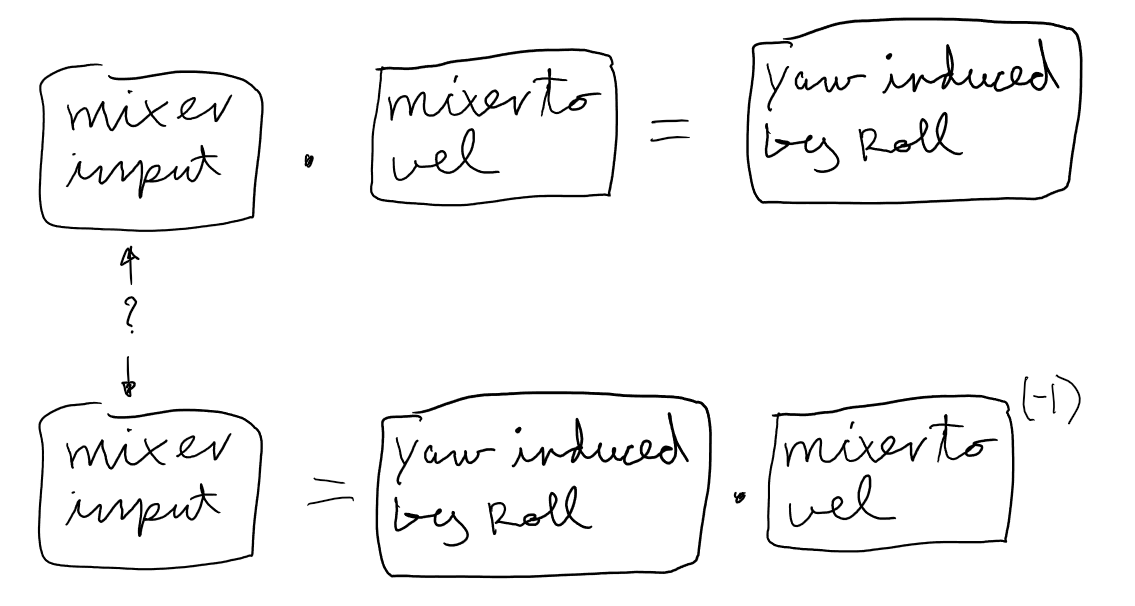

clf
s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



sort(pole(H_yaw_mixer_to_vel_trimmed))

ans = 1.0e+03 *

  -0.0000 - 0.0007i
  -0.0000 + 0.0007i
  -0.0025 + 0.0000i
   0.0024 - 0.0012i
   0.0024 + 0.0012i
  -0.0050 - 0.0009i
  -0.0050 + 0.0009i
  -0.0150 + 0.0000i
   0.0132 - 0.0118i
   0.0132 + 0.0118i


zpk(H_yaw_mixer_to_vel_trimmed)

ans =
 
  From input "Yaw mixer" to output "Yaw velocity":
                                                                                                                                
  561.75 (s+400) (s+17.8) (s+6.89) (s+5.963) (s-3.138) (s-1.484) (s+0.08195) (s^2 - 0.5903s + 211.4) (s^2 + 84.66s + 2134)      
                                                                                                                                
                                                                                                           (s^2 - 4.059s + 3526)
                                                                                                                                
  ------------------------------------------------------------------------------------------------------------------------------
                                                                                                                                
  (s+1281) (s+15.05) (s+2.5) (s^2 + 0.

zpk(minreal(H_yaw_mixer_to_vel_trimmed*(s^2 - 4.878*s + 7.326)*(s^2 - 26.47*s + 314.9),tol))

ans =
 
  From input to output "Yaw velocity":
                                                                                                                                
  561.75 (s+400) (s+17.8) (s+6.89) (s+5.963) (s-3.138) (s-1.484) (s+0.08195) (s^2 - 0.5903s + 211.4) (s^2 + 84.66s + 2134)      
                                                                                                                                
                                                                                                           (s^2 - 4.059s + 3526)
                                                                                                                                
  ------------------------------------------------------------------------------------------------------------------------------
                                                                                                                            
     (s+1281) (s+15.05) (s+2.5) (s^2 + 0.037s + 0.5238

minreal(ans*1/(s+1e5)*1/(s+1e6))

ans =
 
  From input to output "Yaw velocity":
                                                                                                                                     
       561.75 (s+400) (s+17.8) (s+6.89) (s+5.963) (s-3.138) (s-1.484) (s+0.08195) (s^2 - 0.5903s + 211.4) (s^2 + 84.66s + 2134)      
                                                                                                                                     
                                                                                                                (s^2 - 4.059s + 3526)
                                                                                                                                     
  -----------------------------------------------------------------------------------------------------------------------------------------
                                                                                                                                           
  (

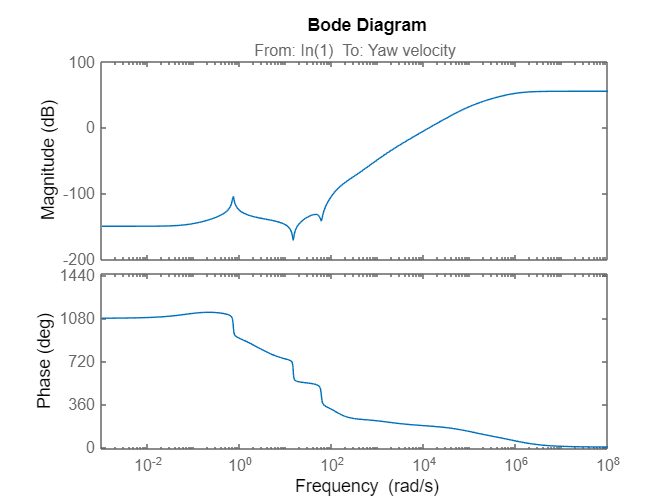

bode(ans)

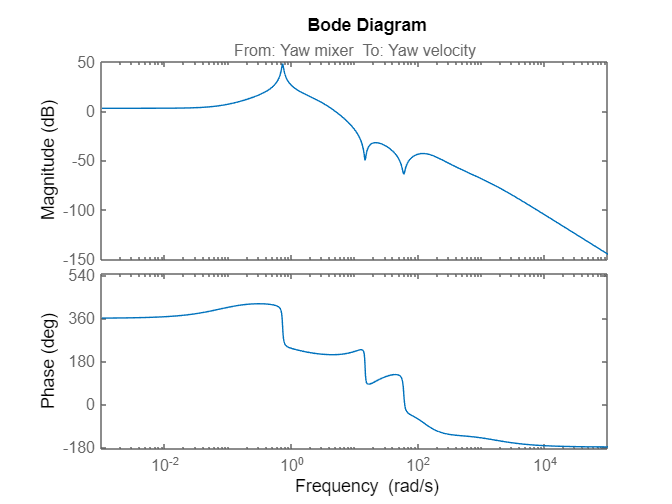

bode(H_yaw_mixer_to_vel_trimmed)

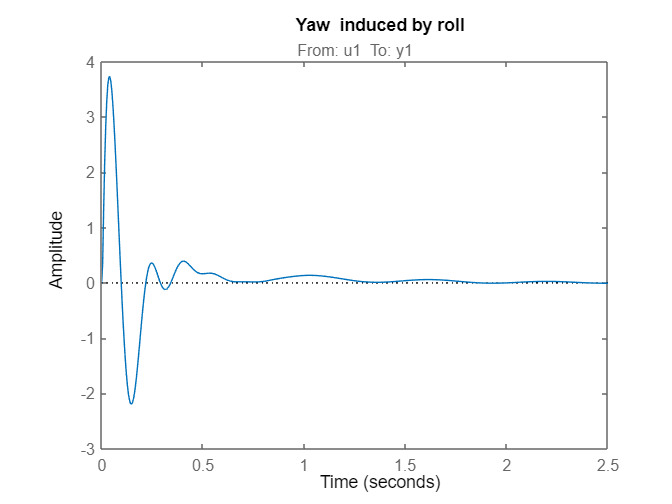

step(p12z12)
title("Yaw  induced by roll")

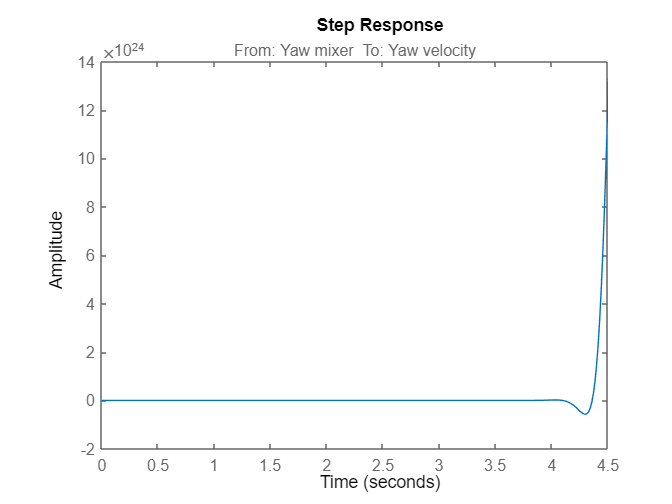

step(H_yaw_mixer_to_vel_trimmed)

H_yawInduced=p12z12;
H_mixerInput=minreal(H_yawInduced/H_yaw_mixer_to_vel_trimmed)

H_mixerInput =
 
  From input "Yaw velocity" to output "y1":
                                                                                                                                    
  -3.041e-05 s^27 - 0.4239 s^26 - 402.6 s^25 + 1.555e05 s^24 + 5.769e07 s^23 + 1.003e10 s^22 + 8.841e11 s^21 + 4.73e13 s^20         
                                                                                                                                    
          + 1.798e15 s^19 + 4.422e16 s^18 + 4.985e17 s^17 + 8.394e18 s^16 + 2.064e20 s^15 + 3.838e21 s^14 + 5.963e22 s^13           
                                                                                                                                    
          + 6.166e23 s^12 + 4.671e24 s^11 + 2.261e25 s^10 + 4.877e25 s^9 - 2.172e25 s^8 - 2.848e26 s^7 - 3.409e26 s^6 + 2.71e27 s^5 
                                                                                                                                    
        

zpk(H_mixerInput)

ans =
 
  From input "Yaw velocity" to output "y1":
                                                                                                                                      
    -3.0408e-05 (s+1.288e04) (s+1281) (s-506) (s+15.05) (s+2.5) (s+1.591) (s-0.007689) (s^2 + 0.037s + 0.5238) (s^2 + 10.04s + 26.07) 
                                                                                                                                      
            (s^2 - 4.878s + 7.326) (s^2 + 1.913s + 9.577) (s^2 + 7.706s + 93.3) (s^2 + 2.612s + 120.1) (s^2 - 26.47s + 314.9)         
                                                                                                                                      
                                                                (s^2 + 107s + 3037) (s^2 + 17.38s + 2125) (s^2 + 147.8s + 1.574e04)   
                                                                                                                                      
  -

pole(H_mixerInput)

ans = 1.0e+02 *

  -4.4789 + 0.0000i
  -4.0000 + 0.0000i
   0.0203 + 0.5934i
   0.0203 - 0.5934i
  -0.4233 + 0.1851i
  -0.4233 - 0.1851i
  -0.0856 + 0.3985i
  -0.0856 - 0.3985i
  -0.1808 + 0.3295i
  -0.1808 - 0.3295i


isstable(H_mixerInput)

ans = logical
   0


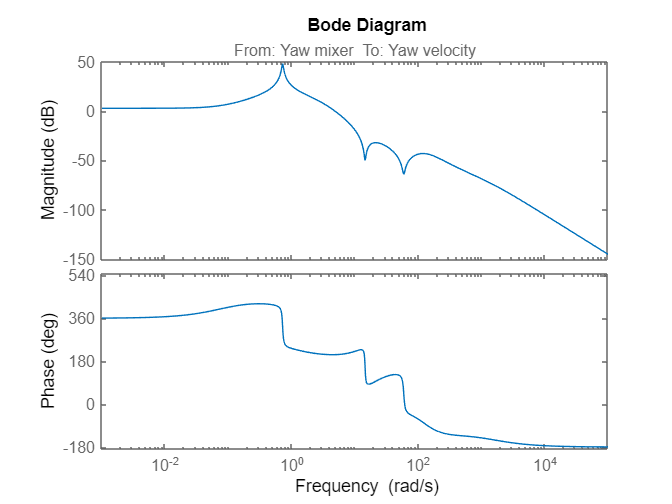

%ustabil og har flere poler end zeros
bode(H_yaw_mixer_to_vel_trimmed)

spike=100

spike = 100

%u=[zeros(spike,1);ones(spike,1);zeros(5000-spike*2,1)]
syms t
u(t)=piecewise(t<1 & t>0,-t+1,0)

$$u(t) = \left\{ \begin{array}{cl} 1-t & \text{ if }t\in \left(0,1\right)\\ 0 & \mathrm{otherwise} \end{array}\right.$$

u_sampel=double(u(time-1))

u_sampel =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



pole(1/(s+1))

ans = -1

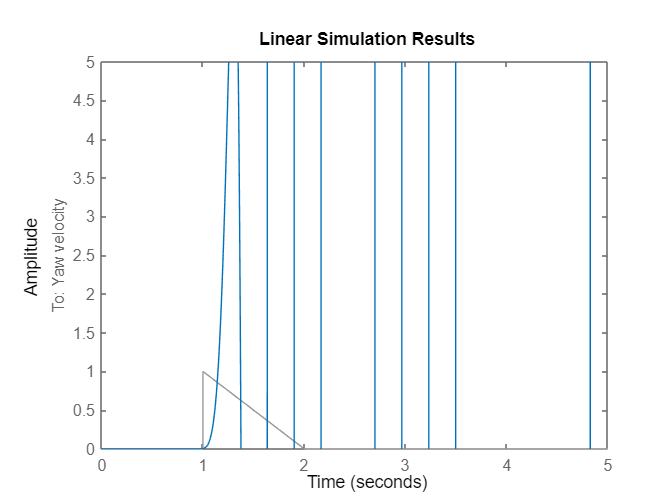

lsim(H_yaw_mixer_to_vel,u_sampel,time)
ylim([0 5])

%clear all
cd("C:\Users\User\OneDrive\DTU\DTU 4-2-2020\DTU\6. semester\bachelor projekt\Previous work\Bachelor-main\Bachelor-main\Simulation_Bachelor_Project\Matlab")
load("crossCouplingV2.mat")
H_yaw_mixer_to_vel

H_yaw_mixer_to_vel =
 
  From input "u1" to output "y1":
     0.1044 s + 15.33
  -----------------------
  s^2 + 2.332 s + 0.00233
 
Name: p2z1
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 1
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using TFEST on time domain data "mydata".
Fit to estimation data: 98.84% (stability enforced)
FPE: 0.004215, MSE: 0.00421                        


H_yaw_induced

H_yaw_induced =
 
  From input "u1" to output "y1":
           9.251e04 s^4 + 9.816e05 s^3 + 3.548e06 s^2 + 1.139e07 s - 3.76e05
  ------------------------------------------------------------------------------------
  s^6 + 510.2 s^5 + 1.507e04 s^4 + 6.743e05 s^3 + 5.909e06 s^2 + 5.391e07 s + 4.874e07
 
Name: p6z4
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 6   Number of zeros: 4
   Number of free coefficients: 11
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using TFEST on time domain data "mydata".
Fit to estimation data: 91.44% (stability enforced)
FPE: 0.6166, MSE: 0.6124                           


zpk(H_yaw_mixer_to_vel)

ans =
 
  From input "u1" to output "y1":
     0.10435 (s+146.9)
  -----------------------
  (s+2.331) (s+0.0009996)
 
Name: p2z1
Continuous-time zero/pole/gain model.



p=pole(H_yaw_mixer_to_vel)

p =    -2.3313
   -0.0010


z=zero(H_yaw_mixer_to_vel)

z = -146.9118

H_yaw_mixer_to_vel_NEW=zpk(z,[p(1),0],0.10435)

H_yaw_mixer_to_vel_NEW =
 
  0.10435 (s+146.9)
  -----------------
     s (s+2.331)
 
Continuous-time zero/pole/gain model.



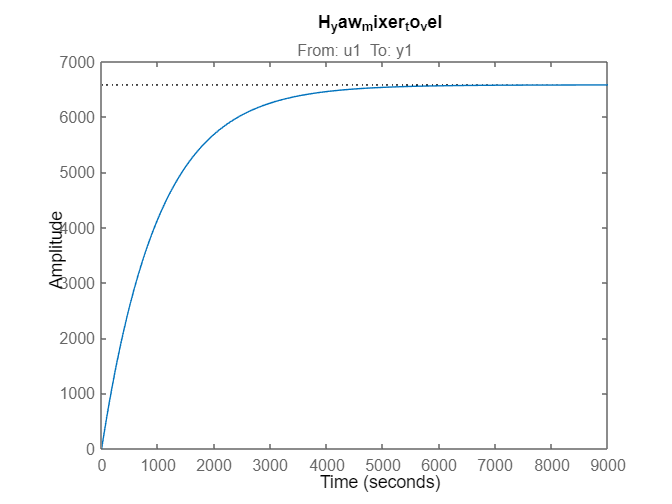

step(H_yaw_mixer_to_vel)
title("H_yaw_mixer_to_vel")

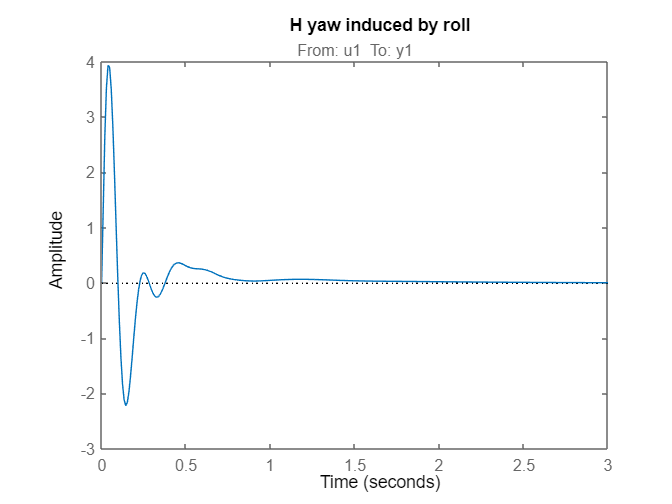

step(H_yaw_induced)
title("H yaw induced by roll")

D=H_yaw_induced;G=H_yaw_mixer_to_vel;G=H_yaw_mixer_to_vel_NEW;
zero(G)

ans = -146.9118

H_mixerInput=minreal(D/G)

H_mixerInput =
 
  From input to output "y1":
      8.8653e05 s (s+7.716) (s+2.331) (s-0.03268) (s^2 + 2.927s + 16.12)
  --------------------------------------------------------------------------
  (s+481.8) (s+146.9) (s+1.002) (s^2 + 8.108s + 91.92) (s^2 + 19.31s + 1099)
 
Continuous-time zero/pole/gain model.



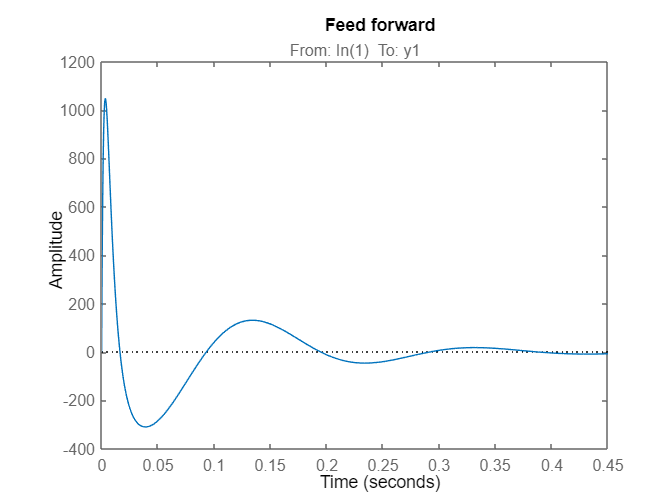


step(H_mixerInput)
title("Feed forward")

[numRollYawFF denumRollYawFF] = tfdata(H_mixerInput, 'v')

numRollYawFF = 1.0e+08 *

         0    0.0089    0.1147    0.5593    1.8840    2.5082   -0.0840         0


denumRollYawFF = 1.0e+09 *

    0.0000    0.0000    0.0001    0.0029    0.1050    0.9220    7.9694    7.1609



syms t
u(t)=piecewise(t<0.5 & t>0,-t*2+1,0)

$$u(t) = \left\{ \begin{array}{cl} 1-2\,t & \text{ if }t\in \left(0,\frac{1}{2}\right)\\ 0 & \mathrm{otherwise} \end{array}\right.$$

u_sampel=double(u(time-1))

u_sampel =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



pole(1/(s+1))

ans = -1

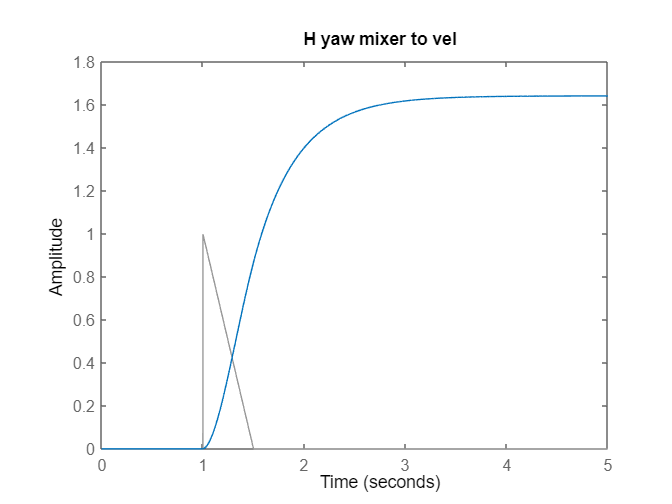

lsim(H_yaw_mixer_to_vel,u_sampel,time)
title("H yaw mixer to vel")